filepath = "./data/";
filename_va = "viola.wav";

[s_va,fs] = audioread(filepath + filename_va);
if mod(length(s_va), 2)
s_va = s_va(1:end-1) * 0.8 /max(abs(s_va));
end
%sound(s_va, fs); pause(3)
duration = length(s_va) / fs;

Viola（原音）一番低いDのスペクトル

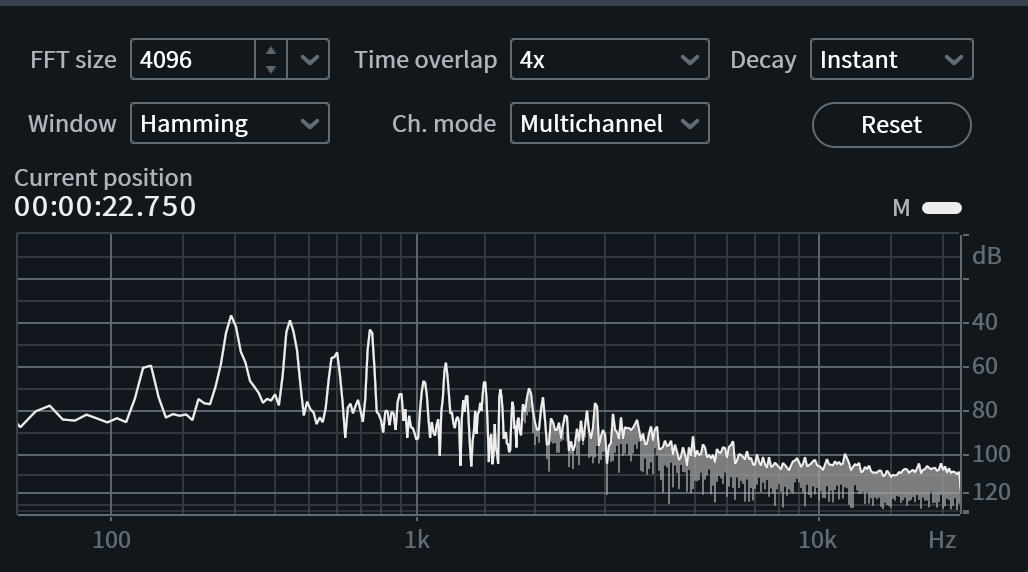

Viola（原音）もう少し高い音

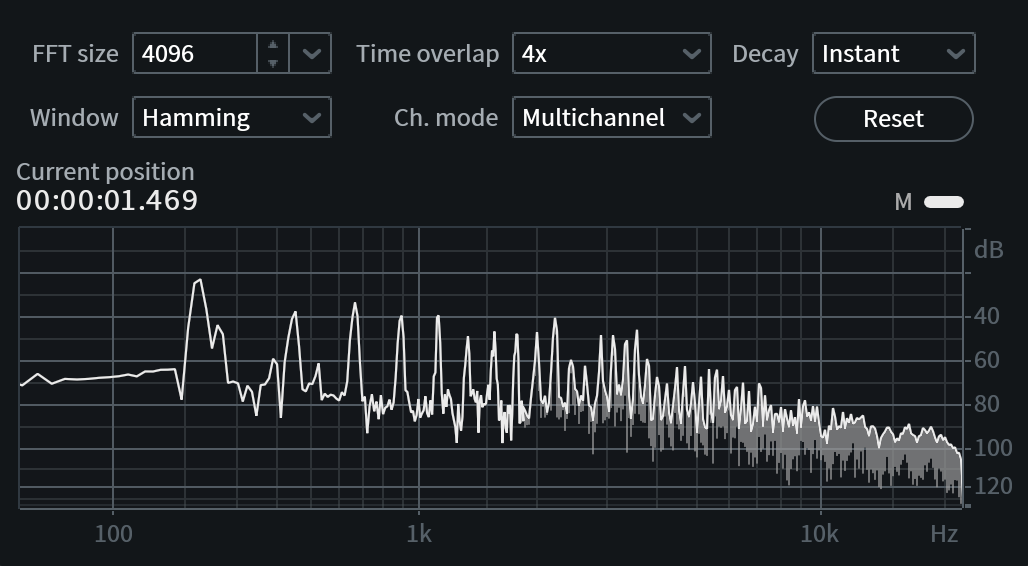

1kHz より上あたりからpeak-to-sidelobe ratio が低くなってくる

＝サイン波とそれ以外のコンポーネントで区別がつきにくい..?

N = length(s_va);
fnq = ceil(fs/2);
hamWin = hamming(N);
axis_freq = fs * (1:N) / N;

alpha = 0.5;

% 重音に弱い、トランジェントがきつい、ビブラートもきつい
s_va_wsola = wsolaTSM(s_va, alpha);
s_va_wsola_resample = lowpass(resample(s_va_wsola, 2, 1), fnq/2, fs);
sound(s_va_wsola_resample, fs); pause(length(s_va)/fs + 1)

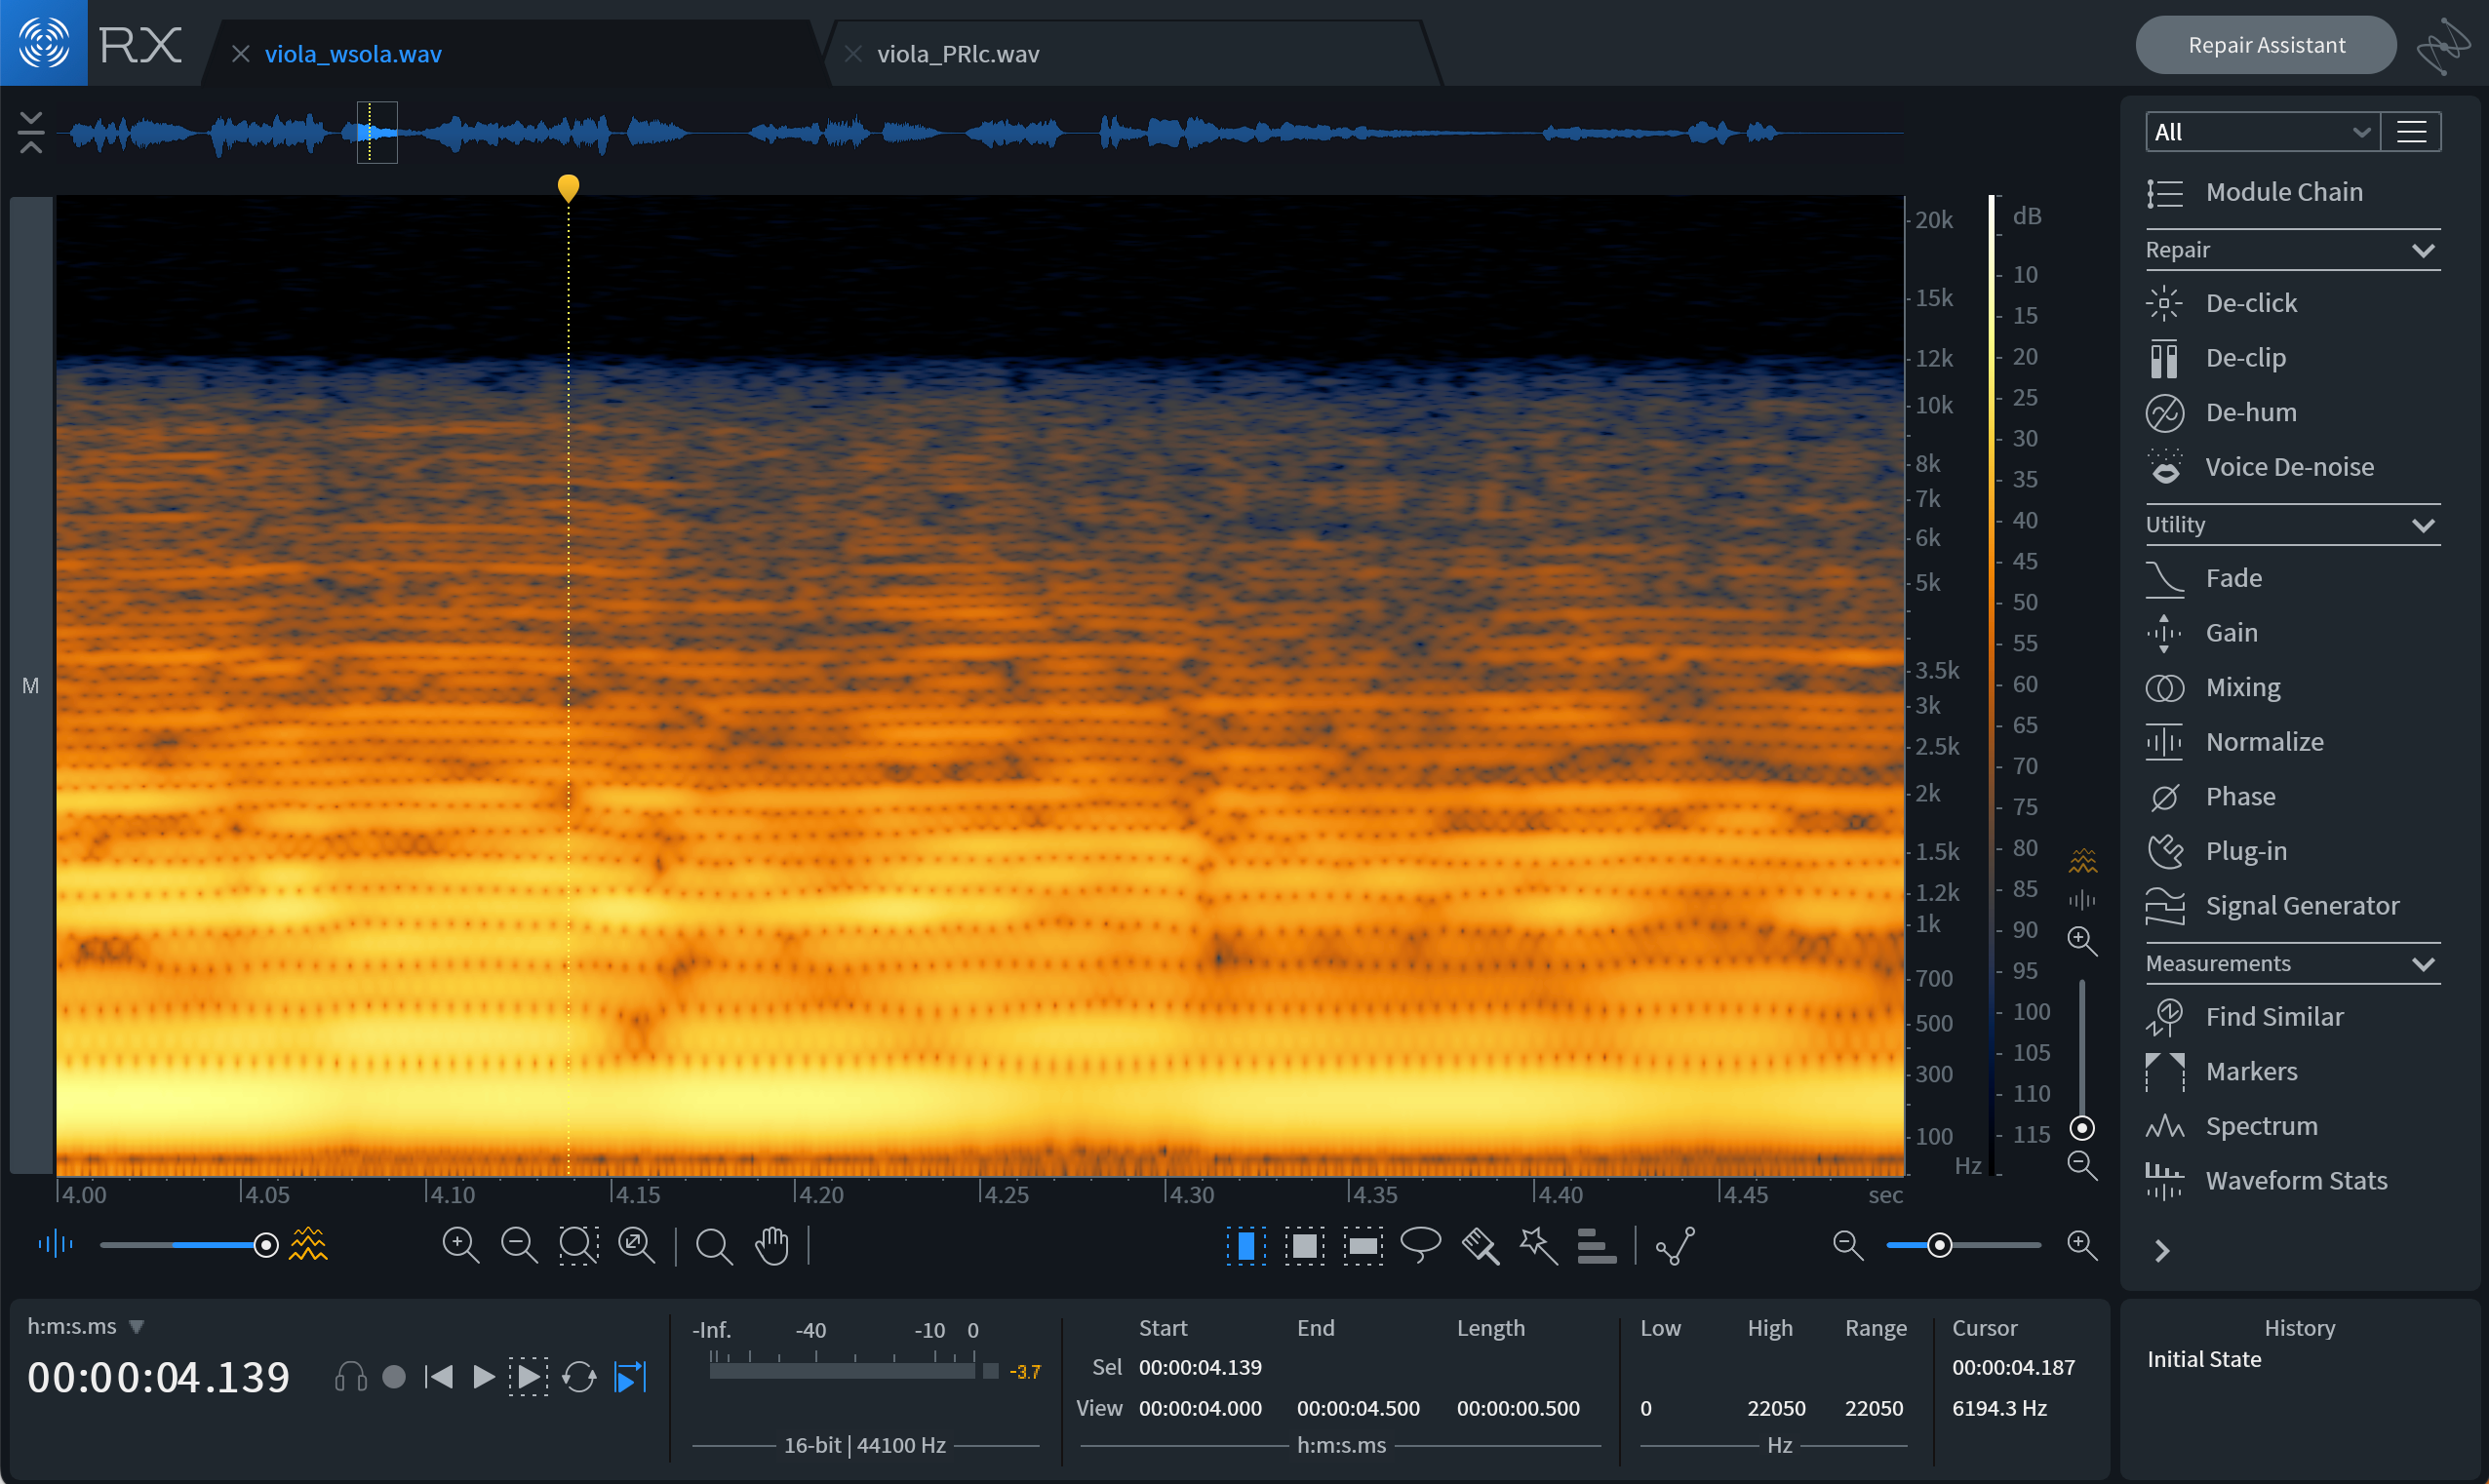

#### setting parameters

parameter.pvSynHop = 512;
parameter.pvWin = win(2048,2); % hann
parameter.pvZeroPad = 0;
parameter.pvRestoreEnergy = 0;
parameter.pvFftShift = 0;
parPv.synHop = parameter.pvSynHop;
parPv.win = parameter.pvWin;
parPv.zeroPad = parameter.pvZeroPad;
parPv.restoreEnergy = parameter.pvRestoreEnergy;
parPv.fftShift = parameter.pvFftShift;
parPv.phaseLocking = 1;

## adapting Phase Vocoder

yPV = pvTSM(s_va, alpha, parPv);
% yPV = wsolaTSM(s_va, alpha);
yPVr = resample(yPV,2,1);
yPVrl = lowpass(yPVr, fnq/2, fs);
sound(yPVrl, fs); pause(length(yPVrl)/fs + 1)

% plotLogLogSpectol(fs, yPVr, s_va_wsola_resample);

wsolaとPVでは，（FFTパワースペクトル上では）差がわからない．

FFTの解像度が悪いのか，あるいは位相の問題が大きいのか．

波形の差を見る（上段：ヴィオラ，中段：WSOLA，下段：PV）

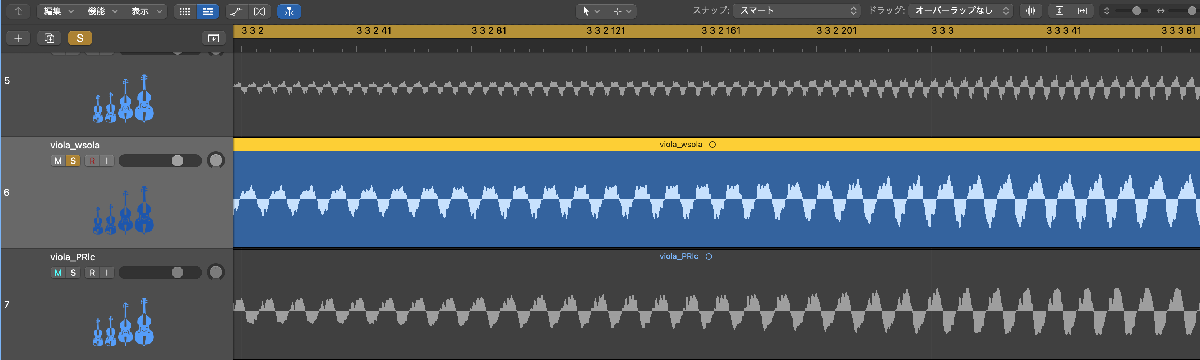

一旦1kHz以上を緩やかにカットした信号に対してWsolaをかけてみる

fth = 400;
y_l = lowpass(s_va, fth, fs,'Steepness', 0.5);
y_l_wsola_r = resample(wsolaTSM(y_l, 0.5), 2, 1);
sound(y_l_wsola_r,fs); pause(duration)

次に1kHz以上の信号に対してPhaseVocoderを使用

y_h = highpass(s_va, fth, fs, 'steepness', 0.5);
y_h_pv_r = resample(pvTSM(y_h,alpha, parPv),2,1);
sound(y_h_pv_r, fs); pause(duration)

混ぜたもの

mix = y_h_pv_r + y_l_wsola_r;
sound(mix, fs); pause(duration);

なんかchorusかけたみたいになってる

gain_pre = 2;
harm_odd = 0.8 * asymmetricCubicSoftClipper(gain_pre * yPVrl);
soundsc(harm_odd(1:2*fs), fs); pause(3);
ratio = 0.1 % [0,1]

ratio = 0.1000

harm_even = (1-ratio) * yPVrl + ratio * abs(yPVrl);
soundsc(harm_even(1:2*fs), fs); pause(3)

soundsc(yPVrl(1:2*fs), fs); pause(3)
soundsc(s_va_wsola_resample(1:1e5), fs)

wsolaがチェロ特有のゴリゴリ感を出せるのはphase vocoderではできてない．

トランジェントが改善されたことでむしろチェロらしさを再現できなくなったか．

高域成分を原音から取り出しておく

edge = highpass(s_va, fnq/2, fs, 'Steepness', 0.95);

このままでは処理しにくい